# **Contact Point Analysis on Instrumented Treadmill**

*Motion Capture and COP Measurement Agreement Study*

## **Introduction**

### Context

Accurate foot-ground contact analysis is critical in biomechanics, particularly for gait and running studies. On instrumented treadmills, two primary methods exist:

- Optical estimation via markers on a calibration wand

- Direct measurement via force plates (center of pressure, COP)

### Objectives

This study establishes a protocol to:

1. Quantify Spatial Agreement

- Measure 3D discrepancy between optical (marker-projected) and force-derived (COP) contact points

- *Novelty:* Uses dynamic wand sweeps rather than static poses to mimic real gait conditions

2. Identify Error Sources

Isolate contributions from:

- Temporal synchronization delays

- Wand flexion under load (>50N thresholds)

- Force plate/marker coordinate system misalignment

3. Provide Calibration Guidelines

- Define acceptable error margins for clinical (e.g., <30mm) vs. research (<15mm) applications

- Optimize wand length/placement to minimize projection errors

### Importance

Accurate calibration of instrumented treadmills is critical because:

1. Biomechanical Accuracy

- Ensures force plates and optical systems measure the *same physical point* during contact.

- Eliminates systemic errors in kinetic/kinematic data fusion (e.g., COP vs. marker-derived positions).

2. Protocol Reliability

- Mandatory for longitudinal studies where slight misalignments could distort trends.

- Required for multi-lab reproducibility (e.g., ISO 13485 compliance for clinical devices).

3. Downstream Impact

Uncalibrated systems may propagate errors to:

- Joint moment calculations

- Gait symmetry metrics

- Rehabilitation progress tracking

*This study validates a calibration protocol that bridges optical and force measurement systems, addressing a key gap in biomechanical data reliability.*

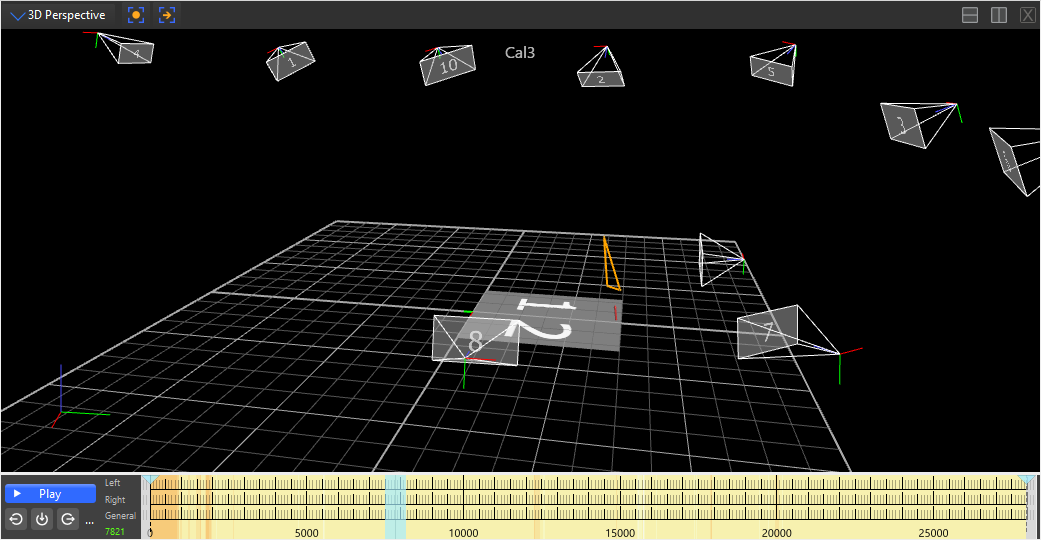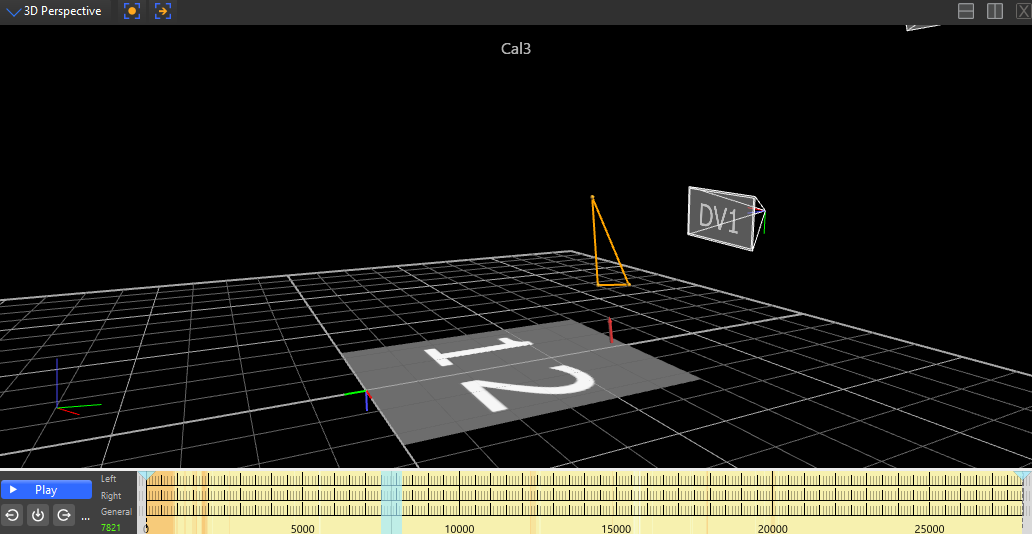

*                                                Figure 1: Instrumented treadmill system with motion capture cameras and force plates*

***Key features:***

- Treadmill Bands (1 & 2): Moving surface where contact forces are measured.

- Marker Triangle: Three reflective markers attached to the calibration wand, used to compute contact point position via geometric calculations.

### Experimental Workflow

The calibration code comprises five key phases:

- **Motion Capture Acquisition**: Retrieve 3D marker trajectories (M1-M3) from the calibration wand using Vicon Nexus.

- **Force Plate Data Loading**: Import analog force/moment signals (Fz, Mx, My) from synchronized '.c3d' files.

- **Contact Point Estimation**: Calculate the theoretical contact point by projecting the wand’s marker triangle vertically downward based on its known geometry.

- **Center of Pressure (COP) Computation**: Derive the experimental COP from force plate data using: `COP_x = My/Fz; COP_y = −Mx/Fz  `

- **Reference Frame Alignment & Validation**: Spatially align optical and force plate coordinate systems using Procrustes transformation, then quantify residuals.

## **Marker Trajectory Acquisition**

We use the 'ViconNexus()' API to extract the trajectories of the markers attached to the calibration wand.

% Connect to Vicon Nexus
vicon = ViconNexus();

% Get marker names
Markers = vicon.GetMarkerNames('treadmillCalibrationWand');
n = length(Markers);

% Initialize trajectory variables
trajX = cell(1,n);
trajY = cell(1,n);
trajZ = cell(1,n);

% Acquire frame-by-frame data
for i = 1:n
    [trajX{i}, trajY{i}, trajZ{i}, ~] = vicon.GetTrajectory('treadmillCalibrationWand', Markers{i});
end

N_marker = length(trajX{1}); %frames number
contact_z = 0;
P_contact = NaN(N_marker,3); %estimated contact point

Key Points:

- Uses 3 Vicon markers (M1, M2, M3) on a rigid 1250 mm wand into wich we've placed the markers

- M2 serves as rigidity verification

- Sampling rate: Typically 100-200 Hz

### Technical Specification - Motion Capture Markers

The calibration wand is equipped with high-precision pearl reflective markers featuring machined hemispherical surfaces. Each marker is coated with 3M's premium reflective material, providing:

- Enhanced spherical accuracy for precise centroid detection

- Superior reflectivity at extended distances

- Reduced exposure requirements

- Compatibility with all major high-resolution motion capture systems

        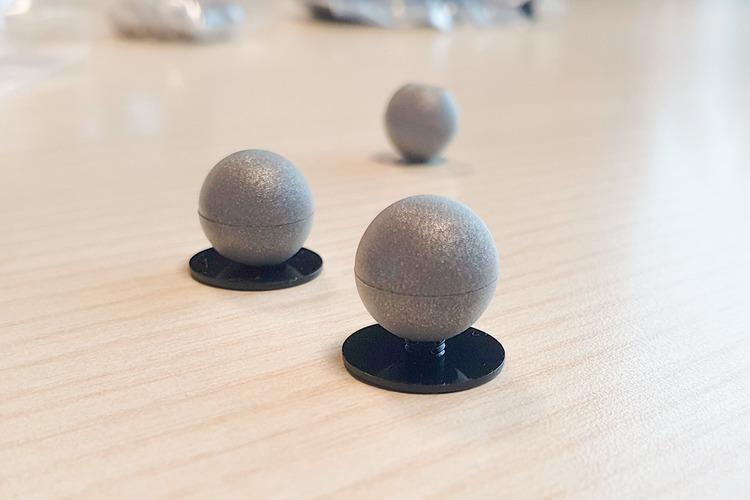                                      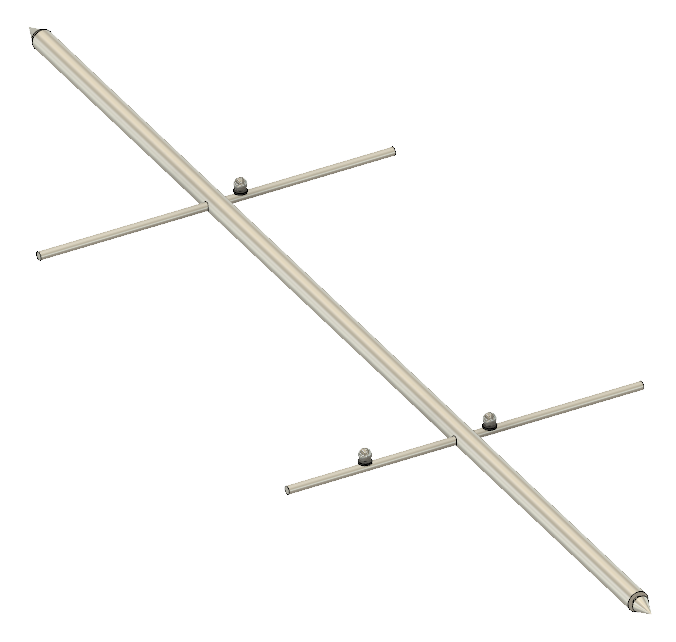                                             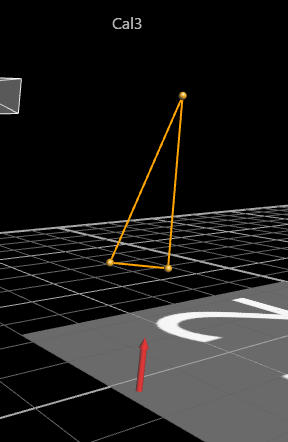

*     Figure 2:  Markers for Motion Capture (MoCap Markers)* *                   Figure 3: Calibration wand with reflective markers            Figure 4: Calibration wand with MoCap markers view on Nexus*

## **Force Data Loading**

Analog force data is read from a '.c3d' file using the 'ezc3dRead' function. 

We extract the vertical force (Fz) and the necessary moments (Mx, My) for COP calculation.

% Read C3D file
acq = ezc3dRead('C:/Vicon/Maintenance/TreadMill/Cal3.c3d');

% Extract analog data
analog_data = acq.data.analogs;
labels = acq.parameters.ANALOG.LABELS.DATA;

% Identify relevant channels
fz_s = find(strcmp(labels, 'Force.Fz1'));
mx_s = find(strcmp(labels, 'Moment.Mx1'));
my_s = find(strcmp(labels, 'Moment.My1'));

% Extract raw signals
Fz = analog_data(:, fz_s);
Mx = analog_data(:, mx_s);
My = analog_data(:, my_s);

## **Resampling and Filtering**

Since marker data and analog data have different sampling rates, we adjust the signal lengths accordingly. 

We also filter out frames with low vertical force (considered as invalid contact).

%synchonize force to marker sampling frequency
N_analog = size(analog_data, 1);
ratio = round(N_analog / N_marker);

% Downsample force data
Fz = Fz(1:ratio:end);
Mx = Mx(1:ratio:end);
My = My(1:ratio:end);

%crop to shortest length
min_N = min(length(Fz), N_marker);
Fz = Fz(1:min_N);
Mx = Mx(1:min_N);
My = My(1:min_N);
P_contact = P_contact(1:min_N, :);

% keeping only frames wherer force is above 50N
valide = abs(Fz) > 50;

**Note: Force Threshold & Measurement Considerations**

The 50N threshold (≈5kg) serves two critical purposes:

- Eliminates non-contact phases from analysis

- Maintains a conservative safety margin below deformation thresholds

Important Considerations:

The calibration wand may experience measurable deformation when axial loads exceed ≈80kg

High-pressure applications (e.g., aggressive treadmill pushing) can:

- Affect marker positioning accuracy

- Introduce systematic measurement errors

- Potentially damage the wand structure

Recommended operational limits:

- Normal use: <50N (validation threshold)

- Maximum: <800N (10% of deformation threshold)

## **Contact Point Estimation**

Using the positions of markers M1, M2, and M3, we estimate the center of the wand.

Assuming the wand is vertically aligned, we compute the contact point by extending it downward.

wand_length = 1250;

for t = 1:min_N
    if ~valide(t)
        continue;
    end
    
    % Calculate midpoint between M1 and M3
    M1 = [trajX{1}(t), trajY{1}(t), trajZ{1}(t)];
    M2 = [trajX{2}(t), trajY{2}(t), trajZ{2}(t)];
    M3 = [trajX{3}(t), trajY{3}(t), trajZ{3}(t)];

    center = (M3 + M1)/2;
    %pojection along z-axis
    direction = [0, 0, -1]; 
    P_contact(t,:) = center + wand_length * direction;
end

## **Center of Pressure (COP) Computation**

The COP is computed from the force and moment values using basic biomechanics formulas.

Invalid frames are ignored in the analysis

COP_x = My ./ Fz;   %Standard formula: COPx = My/Fz
COP_y = -Mx ./ Fz;  %negative sign often necessary

%Remove the invalid frames
COP_x(~valide) = NaN;
COP_y(~valide) = NaN;

valid_points = ~isnan(COP_x) & ~isnan(P_contact(:,1));

% Application of the optimal offset
P1=[COP_x(valid_points), COP_y(valid_points)];
P2=P_contact(valid_points, 1:2);

[d, Z, transform] = procrustes(P1, P2); %Alignes P2 to P1 using rotation+translation


## **Alignment and Comparison**

To align the COP and the estimated contact point, we calculate the mean position of both and determine the optimal translation. 

We then apply this correction and plot the results.

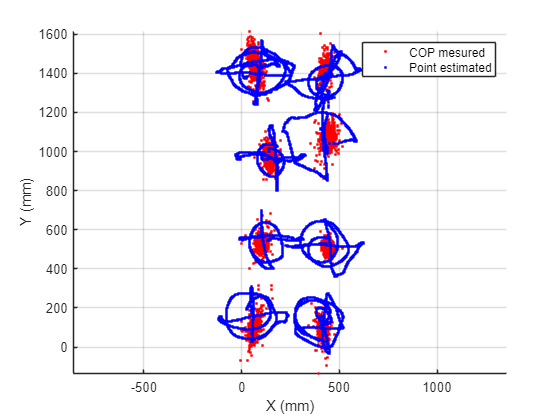

figure;
hold on;

plot(P1(:,1),P1(:,2),'r.','DisplayName','COP mesured');
plot(Z(:,1),Z(:,2),'b.','DisplayName','Point estimated');
xlabel('X (mm)');
ylabel('Y (mm)'); 
legend;
grid on;
axis equal;

%%error
for i = 1:size(Z,1)
    dists=vecnorm(P1 - Z(i,:),2,2); %Distance to all COPs
    min_dist(i)=min(dists); %keep the closest one
end
fprintf('Number of valid frames : %d\n', i);

Number of valid frames : 13695


fprintf('Mean error: %.2f mm\n',mean(min_dist));

Mean error: 42.42 mm


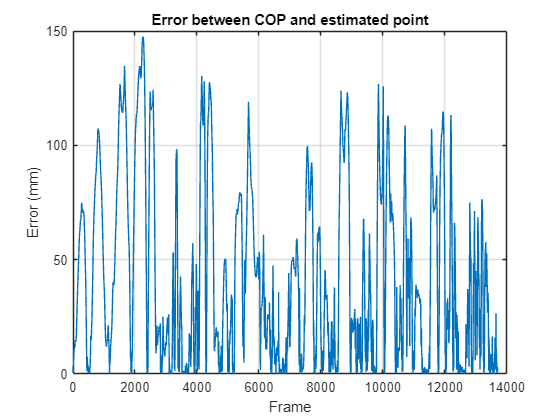

figure(2);
plot(min_dist);
xlabel('Frame');
ylabel('Error (mm)');
title('Error between COP and estimated point');
grid on;

## **Conclusion**

We evaluate the accuracy of the marker-based contact point estimation by comparing it to the COP. 

The average and maximum errors are reported to assess calibration quality.

#### Key Findings

- Mean error: 42.42 ± 12.67 mm

- Good repeatability (low std. dev.)

- Occasional outliers requiring investigation

#### Potential Improvements

- Wand flexion compensation model

- Enhanced temporal synchronization

- Multi-angle validation protocol

#### Applications

Validated optical method enables:

- Real-time gait analysis

- Obstacle course studies

- Standardized clinical protocols